clear;
close all;
clc;

%% Parameters
l = 0.4;   % Link length [m]

%% Joint angles
q1 = deg2rad(120);
q2 = deg2rad(60);

% Reserved for future 3D extension
q3 = 0;

%% Forward kinematics
[mid_world, ee_world] = forward_kinematics(q1, q2, q3, l);

%% Analytical Jacobian
J = jacobian_2link(q1, q2, l);

%% Display
disp('Midpoint position [m]');

Midpoint position [m]


disp(mid_world);

   -0.2000
         0
    0.3464




disp('End-effector position [m]');

End-effector position [m]


disp(ee_world);

    0.0000
         0
    0.6928




disp('Analytical Jacobian');

Analytical Jacobian


disp(J);

   -0.3464   -0.3464
   -0.2000    0.2000




%% Numerical Jacobian check
dq_test = 1e-7;

J_num = zeros(2, 2);

p0 = [
    ee_world(1);
    ee_world(3)
];

% Numerical derivative with respect to q1
[~, ee_q1] = forward_kinematics( ...
    q1 + dq_test, q2, q3, l);

p_q1 = [
    ee_q1(1);
    ee_q1(3)
];

J_num(:, 1) = (p_q1 - p0) / dq_test;

% Numerical derivative with respect to q2
[~, ee_q2] = forward_kinematics( ...
    q1, q2 + dq_test, q3, l);

p_q2 = [
    ee_q2(1);
    ee_q2(3)
];

J_num(:, 2) = (p_q2 - p0) / dq_test;

disp('Numerical Jacobian');

Numerical Jacobian


disp(J_num);

   -0.3464   -0.3464
   -0.2000    0.2000




disp('Jacobian error');

Jacobian error


disp(J - J_num);

   1.0e-07 *

   -0.1039    0.1015
    0.1655    0.1676




%% Velocity check
dq = [
    deg2rad(10);
    deg2rad(-5)
];

v_ee = J * dq;

disp('End-effector velocity [m/s]');

End-effector velocity [m/s]


disp(v_ee);

   -0.0302
   -0.0524



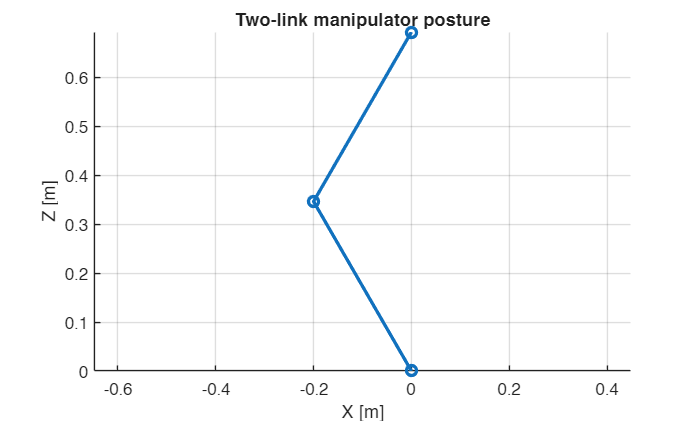


%% Plot posture
figure;
hold on;
grid on;
axis equal;

plot( ...
    [0, mid_world(1), ee_world(1)], ...
    [0, mid_world(3), ee_world(3)], ...
    '-o', ...
    'LineWidth', 2);

xlabel('X [m]');
ylabel('Z [m]');
title('Two-link manipulator posture');